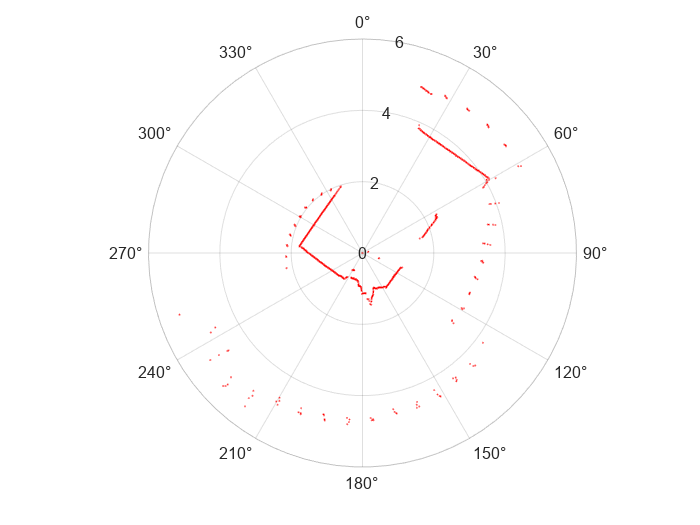

lidar = serialport("COM9", 115200);
count = 0;
while true
    if lidar.NumBytesAvailable > 0
        data = read(lidar,2000,"uint8"); 
        indicesOfHeader = strfind(data,[170 85]);
        packets = {};
        for i = 1:length(indicesOfHeader)-1
            startIdx = indicesOfHeader(i);
            endIdx = indicesOfHeader(i+1);
            packets{end+1} = data(startIdx:endIdx-1);
        end
        for i = 1:length(packets2000at100.Var3)
            interpreter(packets2000at100.Var3{i})
            drawnow;
            count = count + 1;
            if count > 50
                hold off
                count = 0;
            end
        end
    end
    pause(0.1);
end